clc;
clear;
close all;

open("drone_toy_model.mat")

ans = struct with fields:
             R_camera: [3×3×1001 double]
        R_est_history: [3×3×1001 double]
               R_true: [3×3×1001 double]
                a_imu: [1001×3 double]
               a_true: [1001×3 double]
                   ad: [1001×3 double]
        attitude_RMSE: 0.1094
       ba_est_history: [1001×3 double]
       bg_est_history: [1001×3 double]
                   dt: 0.0100
    omega_est_history: [1001×3 double]
            omega_imu: [1001×3 double]
           omega_true: [1001×3 double]
             p_camera: [1001×3 double]
        p_est_history: [1001×3 double]
               p_true: [1001×3 double]
                   pd: [1001×3 double]
        position_RMSE: [0.0154 0.0168 0.0148]
                    t: [1001×1 double]
        v_est_history: [1001×3 double]
               v_true: [1001×3 double]
                   vd: [1001×3 double]
        velocity_RMSE: [0.0644 0.0700 0.0643]
         waypointTime: [6×1 double]
            waypoints: [6×3 double]


%% ========================================================
% STEP 5: SO(3) GEOMETRIC CONTROLLER
%
% INPUTS FROM STEP 2:
%   t
%   pd
%   vd
%   ad
%
% INPUTS FROM STEP 4:
%   p_est_history
%   v_est_history
%   R_est_history
%   omega_est_history
%
% OUTPUTS FOR STEP 6:
%   acceleration_command
%   force_command
%   desired_thrust
%   R_desired_history
%   attitude_error_history
%   torque_command
% ========================================================

%% --------------------------------------------------------
% 1. Load previous results
% ---------------------------------------------------------

load('drone_toy_model.mat');

numSamples = length(t);


%% --------------------------------------------------------
% 2. Check required variables
% ---------------------------------------------------------

requiredVariables = {
    't'
    'pd'
    'vd'
    'ad'
    'p_est_history'
    'v_est_history'
    'R_est_history'
    'omega_est_history'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Run the previous step first.']);

    end

end

%% --------------------------------------------------------
% 3. Gravity and drone parameters
% ---------------------------------------------------------

g = [0; 0; -9.81];

m = 1.0;                         % kg

J = diag([0.02 0.02 0.04]);      % kg*m^2

e3 = [0; 0; 1];

%% --------------------------------------------------------
% 4. Controller gains
% ---------------------------------------------------------

Kp = diag([4 4 6]);

Kv = diag([3 3 4]);

KR = diag([4 4 2]);

Komega = diag([0.15 0.15 0.10]);

%% --------------------------------------------------------
% 5. Storage
% ---------------------------------------------------------

acceleration_command = ...
    zeros(numSamples,3);

force_command = ...
    zeros(numSamples,3);

desired_thrust = ...
    zeros(numSamples,1);

R_desired_history = ...
    zeros(3,3,numSamples);

attitude_error_history = ...
    zeros(numSamples,3);

torque_command = ...
    zeros(numSamples,3);


%% --------------------------------------------------------
% 6. SO(3) geometric controller
% ---------------------------------------------------------

for k = 1:numSamples

    %% ====================================================
    % A. Estimated state from STEP 4
    % ====================================================

    p_hat = ...
        p_est_history(k,:)';

    v_hat = ...
        v_est_history(k,:)';

    R_hat = ...
        R_est_history(:,:,k);

    omega_hat = ...
        omega_est_history(k,:)';

    %% ====================================================
    % B. Position error
    %
    % e_p = p_d - p_hat
    % ====================================================

    e_p = ...
        pd(k,:)' - p_hat;

    %% ====================================================
    % C. Velocity error
    %
    % e_v = v_d - v_hat
    % ====================================================

    e_v = ...
        vd(k,:)' - v_hat;

    %% ====================================================
    % D. Desired acceleration
    %
    % a_c =
    % a_d + K_p e_p + K_v e_v
    % ====================================================

    a_cmd = ...
        ad(k,:)' ...
        + Kp*e_p ...
        + Kv*e_v;

    acceleration_command(k,:) = ...
        a_cmd';

    %% ====================================================
    % E. Desired force
    %
    % F_d = m(a_c - g)
    % ====================================================

    F_desired = ...
        m * (a_cmd - g);

    force_command(k,:) = ...
        F_desired';

    %% ====================================================
    % F. Desired thrust direction
    %
    % b_3d = F_d / ||F_d||
    % ====================================================

    if norm(F_desired) < 1e-8

        b3d = e3;

    else

        b3d = ...
            F_desired / norm(F_desired);

    end

    %% ====================================================
    % G. Desired yaw
    %
    % Yaw follows horizontal velocity direction.
    % ====================================================

    if norm(vd(k,1:2)) > 1e-4

        yaw_d = ...
            atan2( ...
                vd(k,2), ...
                vd(k,1));

    else

        yaw_d = 0;

    end

    b1_heading = [
        cos(yaw_d);
        sin(yaw_d);
        0
    ];

    %% ====================================================
    % H. Construct desired attitude R_d
    % ====================================================

    b2d_temp = ...
        cross(b3d,b1_heading);

    %% Handle singular configuration

    if norm(b2d_temp) < 1e-8

        b1_heading = [1; 0; 0];

        b2d_temp = ...
            cross(b3d,b1_heading);

    end

    %% Normalize second body axis

    b2d = ...
        b2d_temp / norm(b2d_temp);

    %% Construct first body axis

    b1d = ...
        cross(b2d,b3d);

    %% Desired rotation matrix

    Rd = [
        b1d  b2d  b3d
    ];

    %% ====================================================
    % I. Ensure R_d belongs to SO(3)
    %
    % R_d^T R_d = I
    % det(R_d) = 1
    % ====================================================

    [U,~,V] = svd(Rd);

    Rd = U*V';

    if det(Rd) < 0

        U(:,3) = -U(:,3);

        Rd = U*V';

    end

    R_desired_history(:,:,k) = ...
        Rd;

    %% ====================================================
    % J. SO(3) attitude error
    %
    % e_R =
    % 1/2 (R_d^T R - R^T R_d)^vee
    % ====================================================

    E_R = ...
        0.5 * ...
        ( ...
        Rd'*R_hat ...
        - ...
        R_hat'*Rd ...
        );

    e_R = ...
        vee(E_R);

    attitude_error_history(k,:) = ...
        e_R';

    %% ====================================================
    % K. Desired angular velocity
    %
    % For this toy controller:
    %
    % omega_d = 0
    %
    % This is the same simplified formulation used in
    % our current mathematical model.
    % ====================================================

    omega_d = ...
        zeros(3,1);

    %% ====================================================
    % L. Angular velocity error
    %
    % e_omega = omega_hat - omega_d
    % ====================================================

    e_omega = ...
        omega_hat - omega_d;

    %% ====================================================
    % M. Geometric torque controller
    %
    % tau =
    % -K_R e_R
    % -K_omega e_omega
    % + omega x J omega
    % ====================================================

    tau = ...
        -KR*e_R ...
        -Komega*e_omega ...
        +cross( ...
            omega_hat, ...
            J*omega_hat);

    torque_command(k,:) = ...
        tau';

    %% ====================================================
    % N. Required thrust magnitude
    %
    % T = ||F_d||
    % ====================================================

    T = ...
        norm(F_desired);

    desired_thrust(k) = ...
        T;

end

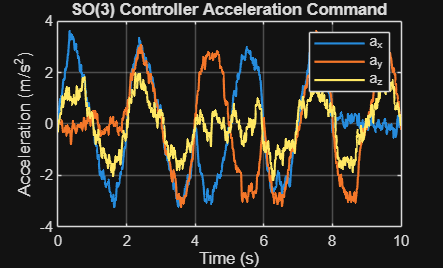


%% ========================================================
% 7. Attitude error magnitude
% =========================================================

attitude_error_magnitude = ...
    sqrt( ...
        sum( ...
            attitude_error_history.^2, ...
            2));

%% ========================================================
% 8. SO(3) validity checks
% =========================================================

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);

for k = 1:numSamples

    R = ...
        R_desired_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm( ...
            R'*R - eye(3), ...
            'fro');

    rotation_determinant_error(k) = ...
        abs(det(R)-1);

end

%% ========================================================
% 9. Position error used by controller
% =========================================================

position_error_history = ...
    pd - p_est_history;

position_error_magnitude = ...
    sqrt( ...
        sum( ...
            position_error_history.^2, ...
            2));

velocity_error_history = ...
    vd - v_est_history;

%% ========================================================
% 10. Plot controller acceleration
% =========================================================

figure;

plot( ...
    t, ...
    acceleration_command(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    acceleration_command(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    acceleration_command(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

title('SO(3) Controller Acceleration Command');

legend( ...
    'a_x', ...
    'a_y', ...
    'a_z');

grid on;

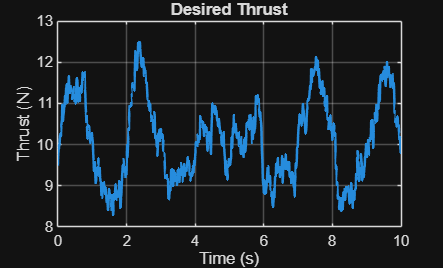


%% ========================================================
% 11. Plot desired thrust
% =========================================================

figure;

plot( ...
    t, ...
    desired_thrust, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Thrust (N)');

title('Desired Thrust');

grid on;

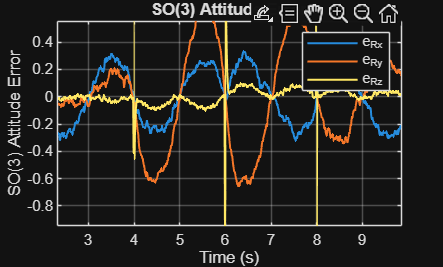


%% ========================================================
% 12. Plot SO(3) attitude error
% =========================================================

figure;

plot( ...
    t, ...
    attitude_error_history(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    attitude_error_history(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    attitude_error_history(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('SO(3) Attitude Error');

title('SO(3) Attitude Error');

legend( ...
    'e_{Rx}', ...
    'e_{Ry}', ...
    'e_{Rz}');

grid on;

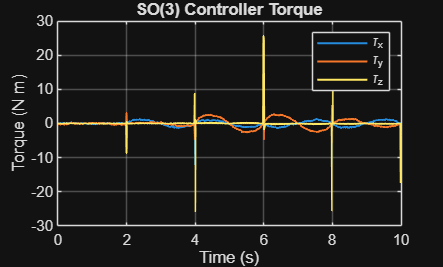


%% ========================================================
% 13. Plot torque
% =========================================================

figure;

plot( ...
    t, ...
    torque_command(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    torque_command(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    torque_command(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Torque (N m)');

title('SO(3) Controller Torque');

legend( ...
    '\tau_x', ...
    '\tau_y', ...
    '\tau_z');

grid on;

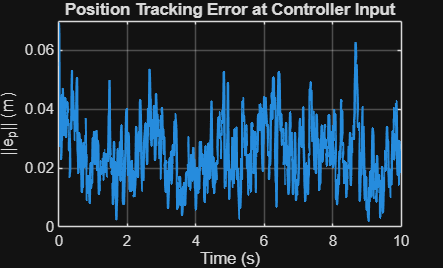


%% ========================================================
% 14. Position error seen by controller
% =========================================================

figure;

plot( ...
    t, ...
    position_error_magnitude, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_p|| (m)');

title('Position Tracking Error at Controller Input');

grid on;


%% ========================================================
% 15. Display results
% =========================================================

fprintf('\n');
fprintf('============================================\n');

fprintf('STEP 5 - SO(3) CONTROLLER RESULTS\n');

STEP 5 - SO(3) CONTROLLER RESULTS


fprintf('============================================\n');


fprintf('\nPosition error RMS:\n');


Position error RMS:



fprintf('X = %.4f m\n', ...
    sqrt(mean(position_error_history(:,1).^2)));

X = 0.0154 m



fprintf('Y = %.4f m\n', ...
    sqrt(mean(position_error_history(:,2).^2)));

Y = 0.0168 m



fprintf('Z = %.4f m\n', ...
    sqrt(mean(position_error_history(:,3).^2)));

Z = 0.0148 m



fprintf('\nVelocity error RMS:\n');


Velocity error RMS:



fprintf('X = %.4f m/s\n', ...
    sqrt(mean(velocity_error_history(:,1).^2)));

X = 0.0644 m/s



fprintf('Y = %.4f m/s\n', ...
    sqrt(mean(velocity_error_history(:,2).^2)));

Y = 0.0700 m/s



fprintf('Z = %.4f m/s\n', ...
    sqrt(mean(velocity_error_history(:,3).^2)));

Z = 0.0643 m/s



fprintf('\nMaximum thrust = %.4f N\n', ...
    max(desired_thrust));


Maximum thrust = 12.4964 N



fprintf('Mean thrust = %.4f N\n', ...
    mean(desired_thrust));

Mean thrust = 10.1390 N



fprintf('\nMaximum torque:\n');


Maximum torque:



fprintf('tau_x = %.4f N m\n', ...
    max(abs(torque_command(:,1))));

tau_x = 12.0304 N m



fprintf('tau_y = %.4f N m\n', ...
    max(abs(torque_command(:,2))));

tau_y = 5.3519 N m



fprintf('tau_z = %.4f N m\n', ...
    max(abs(torque_command(:,3))));

tau_z = 25.5643 N m



fprintf('\nSO(3) attitude error RMS = %.4f\n', ...
    sqrt(mean(attitude_error_magnitude.^2)));


SO(3) attitude error RMS = 0.3699



fprintf('\nMaximum rotation orthogonality error = %.4e\n', ...
    max(rotation_orthogonality_error));


Maximum rotation orthogonality error = 1.5454e-15



fprintf('Maximum determinant error = %.4e\n', ...
    max(rotation_determinant_error));

Maximum determinant error = 8.8818e-16


open("drone_toy_model.mat")

ans = struct with fields:
             R_camera: [3×3×1001 double]
        R_est_history: [3×3×1001 double]
               R_true: [3×3×1001 double]
                a_imu: [1001×3 double]
               a_true: [1001×3 double]
                   ad: [1001×3 double]
        attitude_RMSE: 0.1094
       ba_est_history: [1001×3 double]
       bg_est_history: [1001×3 double]
                   dt: 0.0100
    omega_est_history: [1001×3 double]
            omega_imu: [1001×3 double]
           omega_true: [1001×3 double]
             p_camera: [1001×3 double]
        p_est_history: [1001×3 double]
               p_true: [1001×3 double]
                   pd: [1001×3 double]
        position_RMSE: [0.0154 0.0168 0.0148]
                    t: [1001×1 double]
        v_est_history: [1001×3 double]
               v_true: [1001×3 double]
                   vd: [1001×3 double]
        velocity_RMSE: [0.0644 0.0700 0.0643]
         waypointTime: [6×1 double]
            waypoints: [6×3 double]


%% ========================================================
% 16. Save Step 5 results
% =========================================================

save( ...
    'drone_toy_model.mat', ...
    'waypoints', ...
    'waypointTime', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_camera', ...
    'R_camera', ...
    'a_imu', ...
    'omega_imu', ...
    'p_est_history', ...
    'v_est_history', ...
    'R_est_history', ...
    'omega_est_history', ...
    'ba_est_history', ...
    'bg_est_history', ...
    'acceleration_command', ...
    'force_command', ...
    'desired_thrust', ...
    'R_desired_history', ...
    'attitude_error_history', ...
    'torque_command', ...
    'position_error_history', ...
    'velocity_error_history', ...
    'position_error_magnitude');

fprintf('\nStep 5 results saved to drone_toy_model.mat\n');


Step 5 results saved to drone_toy_model.mat



%% ========================================================
% LOCAL FUNCTIONS
% =========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = vee(S)

    v = [
        S(3,2);
        S(1,3);
        S(2,1)
    ];

end